

ord = 46;

low = 0.4;
bnd = [0.6 0.9];

%fir1 is set with the boundaries and number of N
bM = fir1(ord,[low bnd]);
bW = fir1(ord,[low bnd],'DC-1')

bW =     0.0009    0.0007    0.0005   -0.0000   -0.0008   -0.0019   -0.0034    0.0156   -0.0069   -0.0083   -0.0088    0.0237   -0.0051    0.0000    0.0076   -0.0526    0.0295    0.0430    0.0569   -0.2113    0.0823    0.0917    0.0977    0.6981    0.0977    0.0917    0.0823   -0.2113    0.0569    0.0430    0.0295   -0.0526    0.0076    0.0000   -0.0051    0.0237   -0.0088   -0.0083   -0.0069    0.0156   -0.0034   -0.0019   -0.0008   -0.0000    0.0005    0.0007    0.0009



%fvtool creates the plots for all the fir1s
hfvt = fvtool(bM,1,bW,1)

hfvt =   Figure (filtervisualizationtool) with properties:

      Number: 1
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 1080 533]
       Units: 'pixels'

  Use get to show all properties


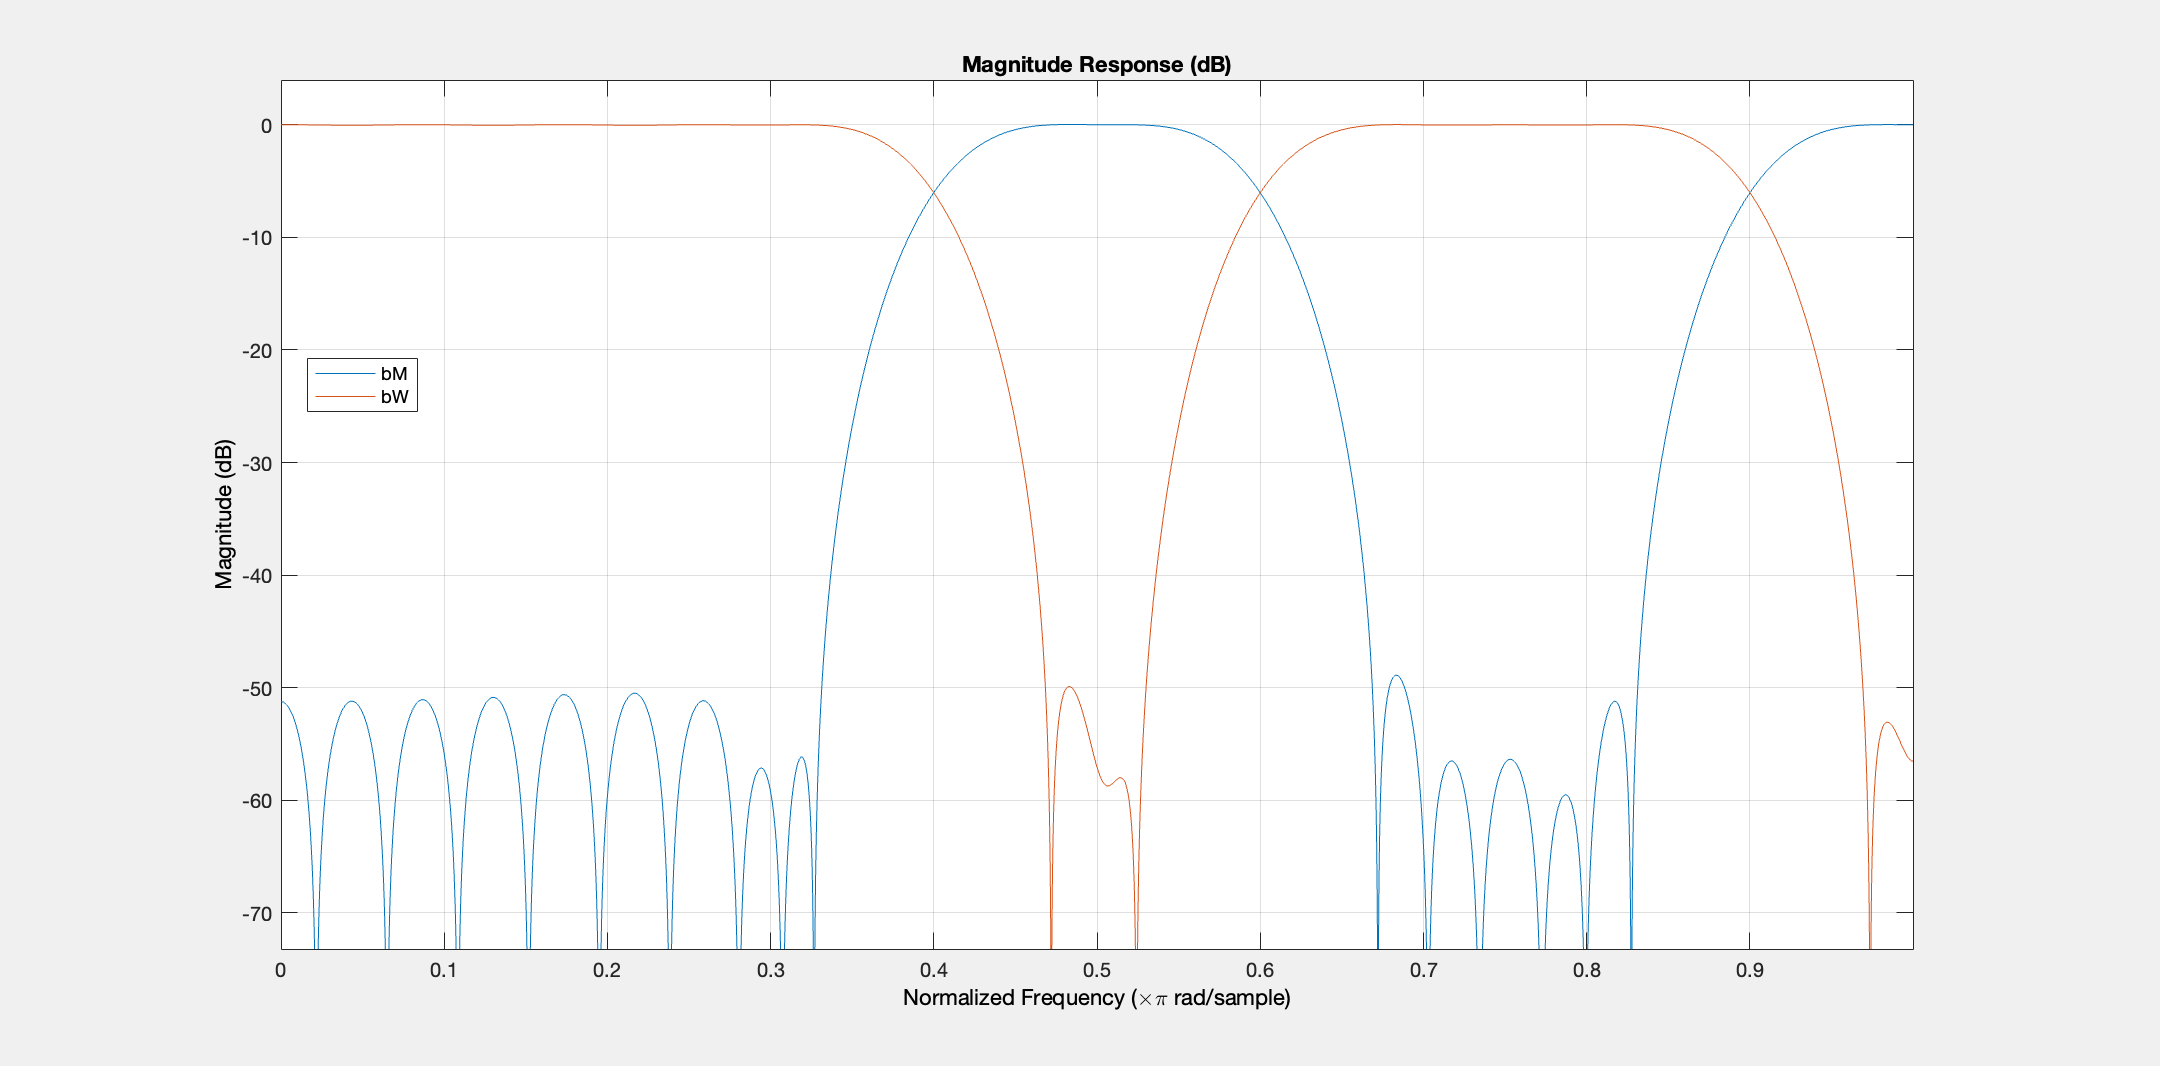

%labeling
legend(hfvt,'bM','bW')

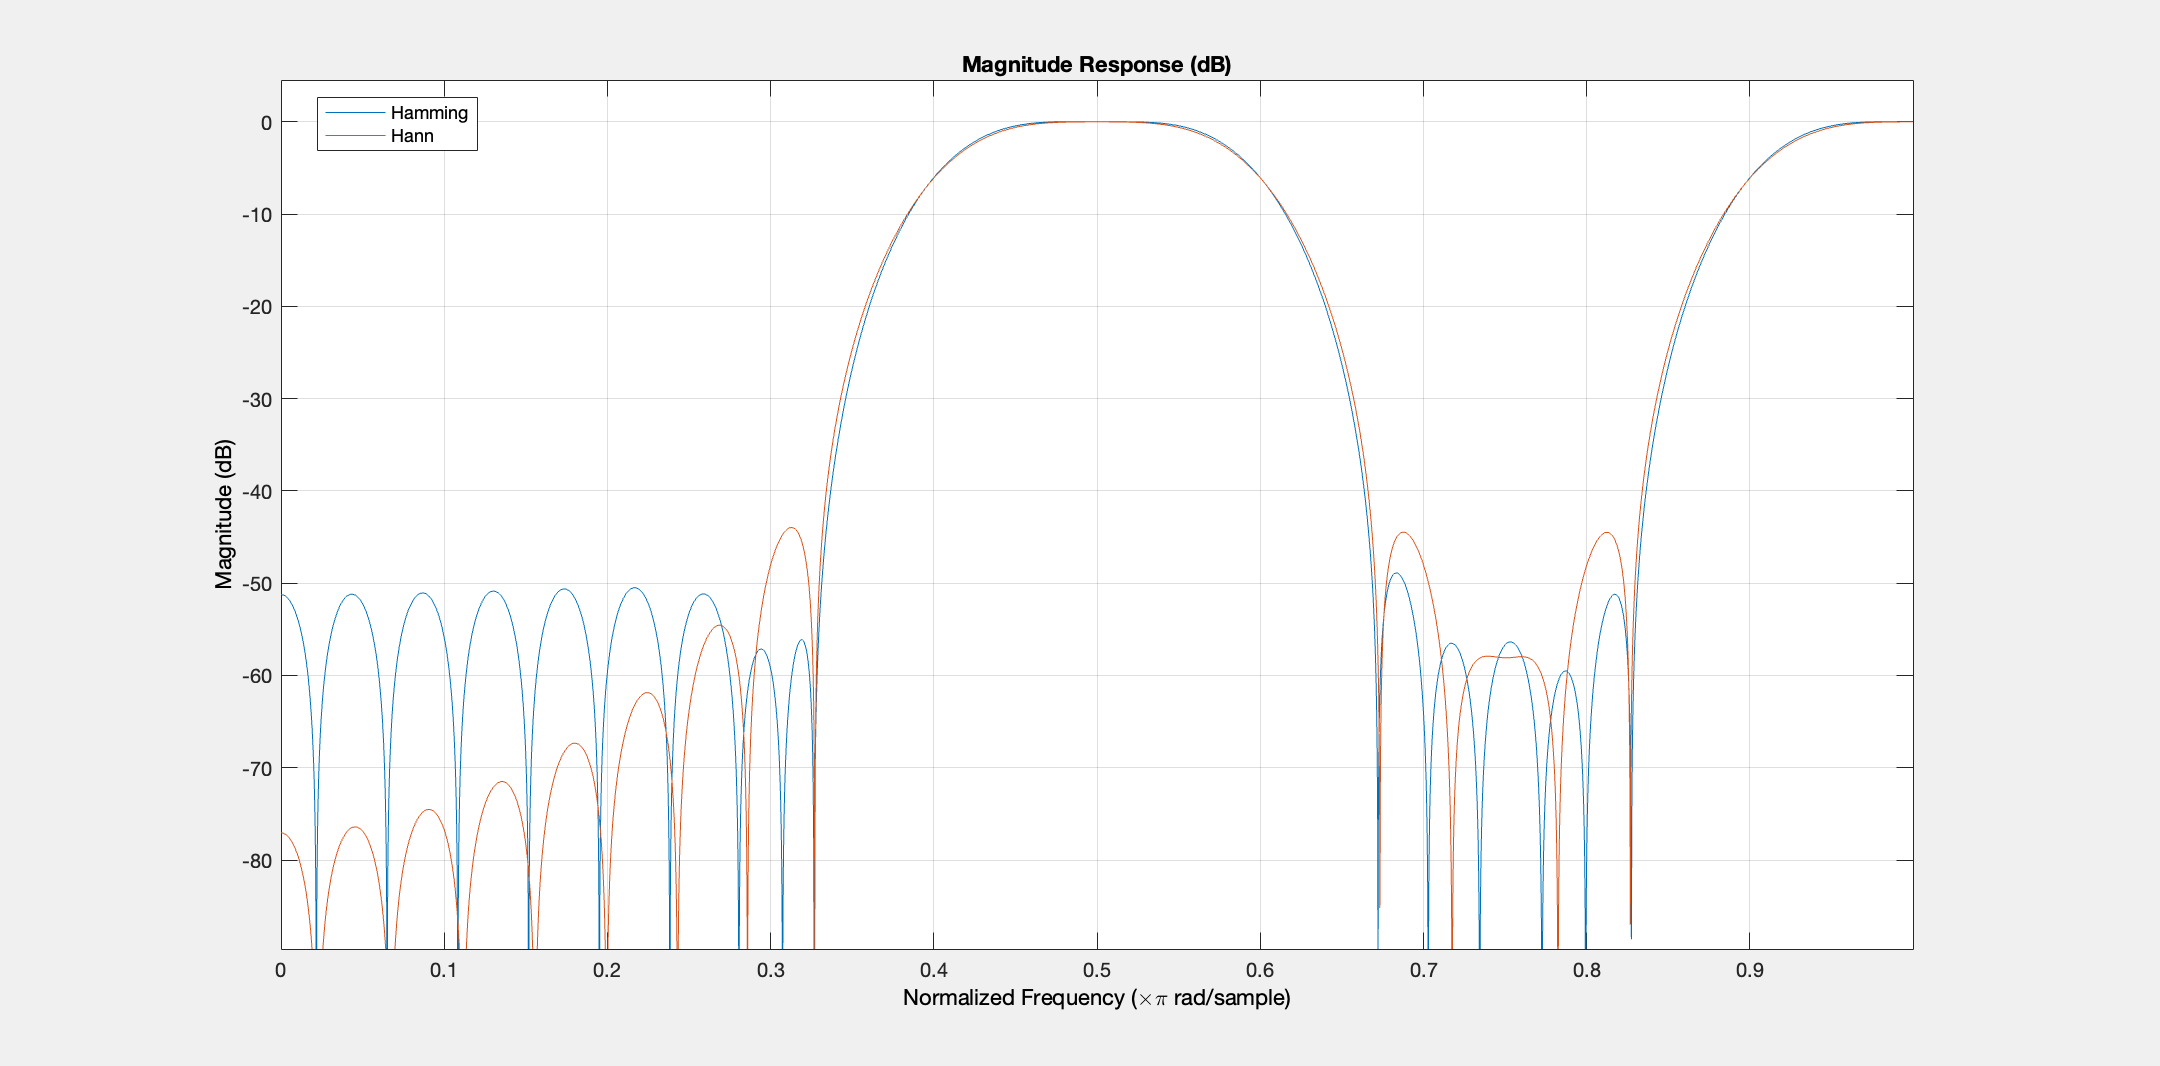

%create fir filter with original boundaries with the 
% first band of a multiband filter is a stopband
hM = fir1(ord,[low bnd],'DC-0',hann(ord+1));

hfvt = fvtool(bM,1,hM,1);
legend(hfvt,'Hamming','Hann')

fir1()

Error using fir1 (line 89)
Not enough input arguments.

%another filter with
% the first band of a multiband filter is a passband 
% and magnitude response of the filter is normalized.
tW = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1));
hfvt = fvtool(bW,1,tW,1);
%label
legend(hfvt,'Hamming','Tukey')